## Experimental Data

**Author:** Surabhi Joshi

## Summary

This script reads in some experimental data and performs exploratory initial statistical analysis to understand how each condition affects the metabolomics before running DFA. 

% download the experimental data
experimental_data = readtable('Barb Nelson Pos Table-20180410 - HL.xlsx', ...
'Sheet', 'TU8902');
% delete row 2 and column 2
experimental_data(:, 'Transition') = []; 

## Create tables for averages and standard deviations. 

Even though this is a simple exercise, try to include a description of what is going on. Especially since the logic looks a little complicated already with several nested functions.

Tabl_aver = experimental_data; 
Tabl_std = experimental_data;

%fill the tables with averages and standard deviations
for n = 2:13;
    Tabl_aver(:,(n)) = num2cell(nanmean(experimental_data{:,n:n+2},2)); % Not sure why you have to turn the numeric array to a cell? Can use ()
    Tabl_std(:,(n)) = num2cell(nanstd(experimental_data{:,n:n+2},[ ],2));
    Tabl_aver(:,(n+2)) = [];
    Tabl_std(:,(n+2)) = [];
    Tabl_aver(:,(n+1)) = [];
    Tabl_std(:,(n+1)) = [];
    % n = n+2; <- this will cause the for loop to skip two additional
    % columns
end 

## Create a corelation matrix, r, and Coefficient of variation CV. 

% create arrays 
m_arr_av = table2array(Tabl_aver(:,2:end)); % Needs a clearer name, like meanMetabolomicsArray. Same for below.
m_arr_std = table2array(Tabl_std(:,2:end));

%r matrix 
r = corrcoef(m_arr_av(:,1:3)); % got NaN when @scampit ran it. This is because there are NaN values. If you fill with 0, you get the correct solution.
corrcoef(m_arr_av, m_arr_av)

### This is scampit's solution to fixing the correlation coefficient matrix heatmap.

Please include your interpretations as text too. 

%m_arr_av(isnan(m_arr_av)) = 0;
%averageCorrMat = corrcoef(m_arr_av)
%heatmap(averageCorrMat)

%CV matrix
CV = m_arr_std ./ m_arr_av

%categorial array of the metabolites
metabolite = categorical(table2array(Tabl_aver(:,1)));

% Remove the RP_Pos stuff using regular expressions. One way is to do the
% following:
%pattern = 'RP_Pos_';
%metaboite = strrep(string(metabolite), pattern, '');

% Your assignment: remove the numbers and underscore from the resulting string. Then make the code remove all of the stuff you don't want. 
% More documentation can be found here: https://www.mathworks.com/help/matlab/ref/strrep.html
% More documentation on regular expressions can be found here: https://www.mathworks.com/help/matlab/matlab_prog/regular-expressions.html

## Create heatmaps to visually understand the standard deviations and averages. 

This is interesting! Make sure X and Y ticks are labeled though - need to see what condition X and metabolite Y are. 

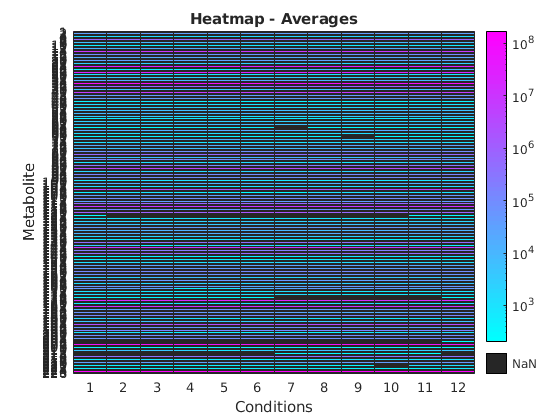

figure (1);
heatmap(m_arr_av, 'ColorScaling', 'log');
xlabel('Conditions');
ylabel('Metabolite');
title('Heatmap - Averages');
colormap 'cool';

%an array of all NaN means for all conditions. These metabolites can be
%discarded from any further calculations. 
allNAN = [];
for i = 1:226
    if isnan(m_arr_av(i,:))
        allNAN = [allNAN; metabolite(i)];
    end
end

% Vectorized implementation to remove NaN from row
% m_arr_av(any(isnan(m_arr_av), 2) = [];

From this figure, I propose that the allNAN to be discarded from any further calculations for teh TU8902 cancer cell line becase they do not have any corresponding data for any of the conditions and are just acting like 'noise'. 

## Scatterplots of the mean and standard deviations

This is also useful. We need to know which metabolite have both high mean and standard deviation.

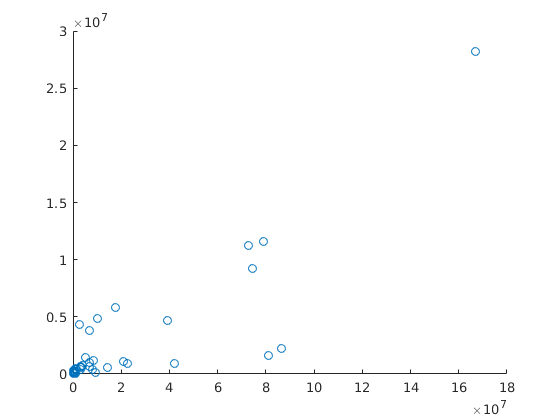

%scatterplots of mean and std
figure (2);
scatter(m_arr_av(:,1), m_arr_std(:,1));

Need to edit figure legend. The argument is 'bestoutside' for the legend argument: [https://www.mathworks.com/help/matlab/ref/legend.html#d120e695500](https://www.mathworks.com/help/matlab/ref/legend.html#d120e695500)

These plots look cool! Maybe make 1 plot of the averages, and separate into nucleotides, lipids, and amino acids. Also, if you know what metabolites belong to glycolysis and TCA, that'd be cool to look at too.

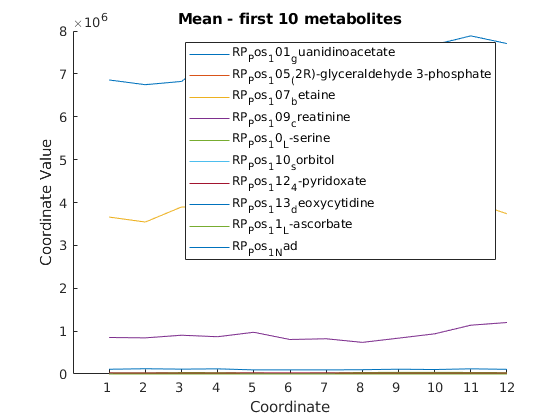

figure (3);
metabolite = categorical(table2array(Tabl_aver(:,1)));
parallelcoords(m_arr_av((1:10),:), 'group', metabolite(1:10));
title('Mean - first 10 metabolites');

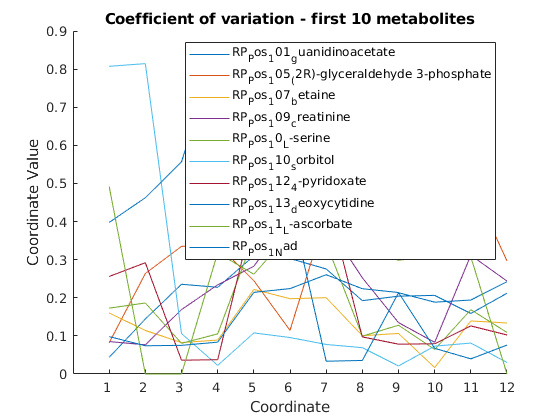

figure (4);
parallelcoords(CV((1:10),:), 'group', metabolite(1:10));
title('Coefficient of variation - first 10 metabolites');

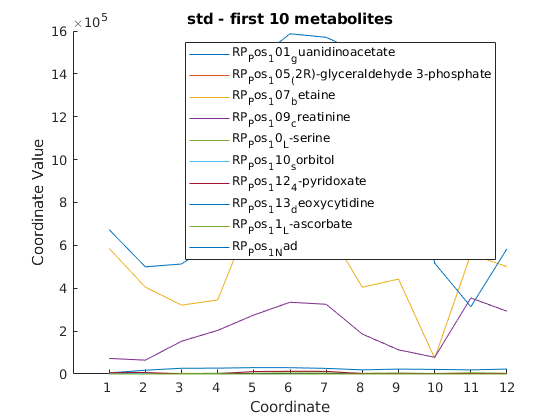

figure (5);
parallelcoords(m_arr_std((1:10),:), 'group', metabolite(1:10));
title('std - first 10 metabolites');

## Hisograms of the mean and standard deviations

%histograms of mean and std

